% 
% copyright 2021 by Thomas P. Weldon
% all rights reserved
%
%Modified by Somto Anyaegbu 05/04/2021
%

clear all
close all hidden
clc

sympref('HeavisideAtOrigin',1); %set equal to 1 as in unitstep

disp('========== Digital Discrete-Time Non-Foster Impedances =========')

========== Digital Discrete-Time Non-Foster Impedances =========


disp('see theory at http://thomasweldon.com/tpw/papers/tpwIscas15digNonFos_22sep2014m_fix_ppt.pdf')

see theory at http://thomasweldon.com/tpw/papers/tpwIscas15digNonFos_22sep2014m_fix_ppt.pdf


clear z th Rser Rser1 Rdac C Ts s Zc Zc1 Hrc Hrc1
syms  z th Rser Rser1 Rdac C Ts s Zc Zc1 Hrc Hrc1

disp('====Parameters Digital non-Foster design ==========:')

====Parameters Digital non-Foster design ==========:


disp('Sample period(T), sample rate(fs), Source Impedance(Rdac), Series Resistance(Rser), latency(th),  and capacitance(C):')

Sample period(T), sample rate(fs), Source Impedance(Rdac), Series Resistance(Rser), latency(th),  and capacitance(C):


Ts= 5 * 10^(-9) %5 ns

Ts = 5.0000e-09

C=-25*10^(-12) %-25 pF

C = -2.5000e-11

Rdac=1000 %1000 Ohms

Rdac = 1000

Rser=0 %0 Ohms

Rser = 0

Rser1=70 %70 Ohms

Rser1 = 70

th = 2.5*10^(-9) %2.5ns

th = 2.5000e-09


disp('')
disp('Find Hrc(z) for the digital capacitor of Rser=0 Ohms and 70 Ohms:')

Find Hrc(z) for the digital capacitor of Rser=0 Ohms and 70 Ohms:


Hrc(z)=(((((Rser*C)-(Rdac*C)+Ts)*z)+((Rdac*C)-(Rser*C)))/((((Rser*C)+Ts)*z)-(Rser*C))); %Hrc(z) with Rser @ 0 Ohms
disp('Hrc(z) of Rser 0 Ohms=')

Hrc(z) of Rser 0 Ohms=


olddigits=digits(); digits(5);vpa(eval(Hrc(z)))

$$ans = \frac{3.3087e-16\,\left(1.8134e+16\,z-1.5112e+16\right)}{z}$$

digits(olddigits);

Hrc1(z)=(((((Rser1*C)-(Rdac*C)+Ts)*z)+((Rdac*C)-(Rser1*C)))/((((Rser1*C)+Ts)*z)-(Rser1*C))); %Hrc(z) with Rser @ 70 Ohms
disp('Hrc(z) of Rser 70 Ohms')

Hrc(z) of Rser 70 Ohms


olddigits=digits(); digits(5);vpa(eval(Hrc1(z)))

$$ans = \frac{2.825e-8\,z-2.325e-8}{3.25e-9\,z+1.75e-9}$$

digits(olddigits);


disp('')
disp('Find Z(s) of Rser=0 Ohms:')

Find Z(s) of Rser=0 Ohms:


Z(s)=subs( (s*Ts*Rdac/((s*Ts) - (((1-1/z)*Hrc(z)*exp(-s*th))))), z, exp(s*Ts));    %Z(s) with Hrc(z)
olddigits=digits(); digits(5);vpa(eval(Z(s)))

$$ans = \frac{3.7779e+17\,s}{3.7779e+14\,s+1.5112e+31\,{\mathrm{e}}^{-2.5e-9\,s}\,{\mathrm{e}}^{-5.0e-9\,s}\,\left({\mathrm{e}}^{-5.0e-9\,s}-1.0\right)\,\left(3.0e-8\,{\mathrm{e}}^{5.0e-9\,s}-2.5e-8\right)}$$

digits(olddigits);

disp('Find Z(s) of Rser=70 Ohms:')

Find Z(s) of Rser=70 Ohms:


Z1(s)=subs( (s*Ts*Rdac/((s*Ts) - (((1-1/z)*Hrc1(z)*exp(-s*th))))), z, exp(s*Ts));      %Z(s) with Hrc1(z)
olddigits=digits(); digits(5);vpa(eval(Z1(s)))

$$ans = \frac{3.7779e+17\,s}{3.7779e+14\,s+\frac{7.5558e+22\,{\mathrm{e}}^{-2.5e-9\,s}\,\left(2.825e-8\,{\mathrm{e}}^{5.0e-9\,s}-2.325e-8\right)\,\left({\mathrm{e}}^{-5.0e-9\,s}-1.0\right)}{3.25e-9\,{\mathrm{e}}^{5.0e-9\,s}+1.75e-9}}$$

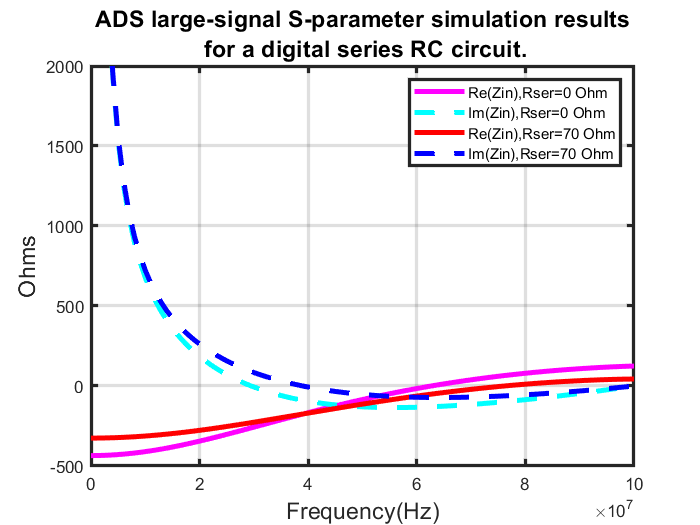

digits(olddigits);

fmax=10^8;fmin=fmax/10^5;
%fmax=10^8;fmin=0;
fn=fmin:(fmax-fmin)/100:fmax;  %linear freq scale
hh=figure(3);
%sp=subplot(3,1,1);
plot(fn,real(vpa(Z(i*2*pi*fn))),'m',fn,imag(vpa(Z(i*2*pi*fn))),'c--', fn,real(vpa(Z1(i*2*pi*fn))),'r',fn,imag(vpa(Z1(i*2*pi*fn))),'b--', 'LineWidth',3);
title({'ADS large-signal S-parameter simulation results',' for a digital series RC circuit.'});
legend({'Re(Zin),Rser=0 Ohm','Im(Zin),Rser=0 Ohm','Re(Zin),Rser=70 Ohm','Im(Zin),Rser=70 Ohm'},'Location','northeast')
grid on;xlim([0 fmax]);ylim([-500 2000]);
set(gca,'LineWidth',2,'ytick',[-500:500:2000]);
set(gca,'LineWidth',2,'xtick',[0:20000000:fmax]);
xlabel('Frequency(Hz)');  ylabel('Ohms');  
set(findall(hh,'Type','text'),'FontSize',14);